clear, close all, clc;

**(1) Define system parameters**

%Constants
m_p = 0.215;    %(kg)       Pendulum mass
m_c = 1.608;    %(kg)       Cart mass
L   = 0.314;    %(m)        Effective pendulum half-length
I_o = 7.06e-3;  %(kg.m^2)   Pendulum moment of inertia about centre of mass
R   = 0.16;     %(ohm)      Motor terminal resistance
r   = 0.0184;   %(m)        Pinion radius
k_g = 3.71;     %(m/m)      Gearing ratio
k_m = 0.0168;   %(V.s/rad)  Motor back EMF constant
c   = 0;        %(N.s/m)    Damping on cart
g   = 9.81;     %(m/s^2)    Acceleration due to gravity
dx  = 0.1;      %(m)        Step size of cart.

%Matricies
A3_2 = (-m_p^2*L^2*g)/((m_c + m_p)*I_o + m_c*m_p*L^2);
A3_3 = (I_o + m_p*L^2)*(c*R*r^2 + k_m^2*k_g^2)/(((m_c + m_p)*I_o + m_c*m_p*L^2)*R*r^2);
A4_2 = (m_c + m_p)*m_p*L*g/((m_c + m_p)*I_o + m_c*m_p*L^2);
A4_3 = -m_p*L*(c*R*r^2 + k_m^2*k_g^2)/(((m_c + m_p)*I_o + m_c*m_p*L^2)*R*r^2);

A = [0,   0,    1,    0;
     0,   0,    0,    1;
     0,   A3_2, A3_3, 0;
     0,   A4_2, A4_3, 0];
 
B3 = -(I_o + m_p*L^2)*k_m*k_g/(((m_c + m_p)*I_o + m_c*m_p*L^2)*R*r);
B4 = m_p*L*k_m*k_g/(((m_c + m_p)*I_o + m_c*m_p*L^2)*R*r);

B = [0;0;B3;B4];

C = [1 0 0 0;
     0 1 0 0]; %eye(4); %make it eye(4) for the real thing, make it [1 0 0 0] so that only x is plotted for easy reading in matlab
D = 0;


**(2) Make state space object**

sys = ss(A, B, C, D);

%check stability
eig(sys);


**(3) Design control gains**

(3.1.1) Place poles method

poles = [-5+3i, -5-3i, -5+3.1i -5-3.1i]; %aggressive but within limits, ~2.86
%degree max
K = place(A, B, poles);

(3.1.2) LQR method


% Q = diag([100, 1, 1, 1]);
% R = 1;
% K = lqr(sys, Q, R);



(3.2) Create system

ACL = A - B*K;
sys = ss(ACL, B, C, D);

%tracking gain N
C1 = [1 0 0 0];
N = -inv(C1*inv(ACL)*B); 

**(4) Responses**

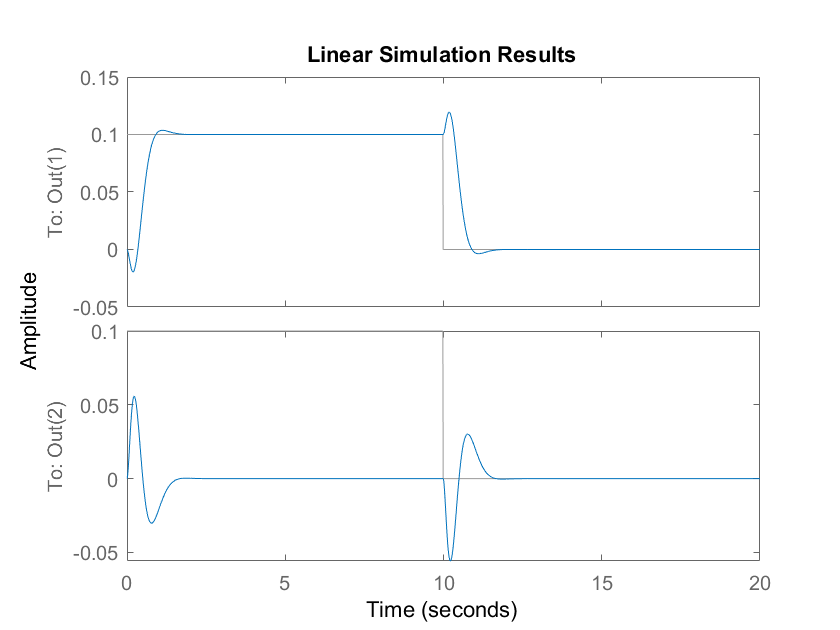


sys.B = N*sys.B; %As it is tracking a dx step input, also include tracking gain N

dt = 0.01;
pulse_duration = 10; %seconds between tracking input steps
num_steps = 2; %number of steps back and forward
tArray = 0:dt:pulse_duration*num_steps; 

rArray = dx*ones(size(tArray));
rArray(pulse_duration/dt:end) = 0;

%Step response
figure
lsim(sys, rArray, tArray);

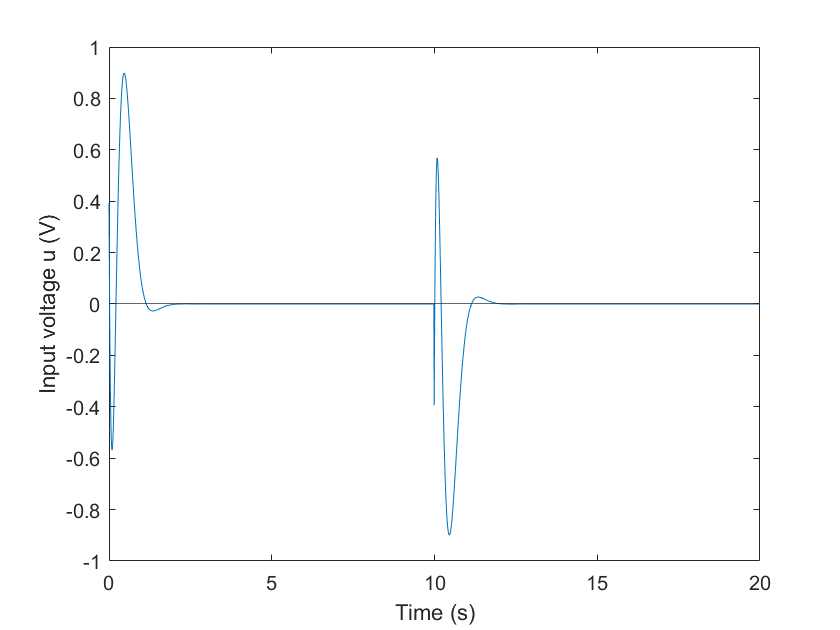



%Voltage
figure
[y, t, x] = lsim(sys, rArray, tArray);
u = -K*transpose(x) + N*rArray;
plot(t, u);
hold on
yline(0);
xlabel("Time (s)")
ylabel("Input voltage u (V)")

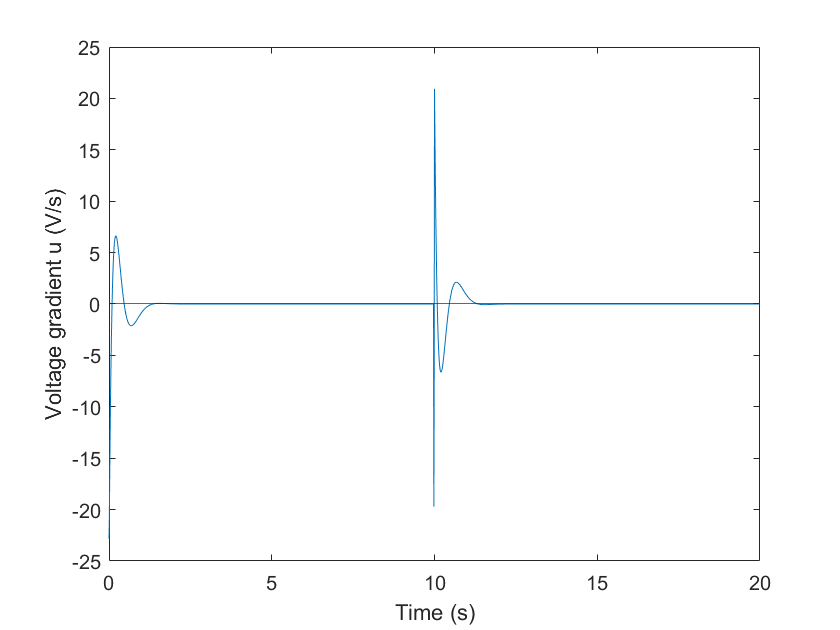



%dv/dt
figure
dudt = gradient(u(:)) ./ gradient(t(:));
plot(t, dudt)
hold on
yline(0);
xlabel("Time (s)")
ylabel("Voltage gradient u (V/s)")


%Print values
stepinfo(sys)

ans = 2×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


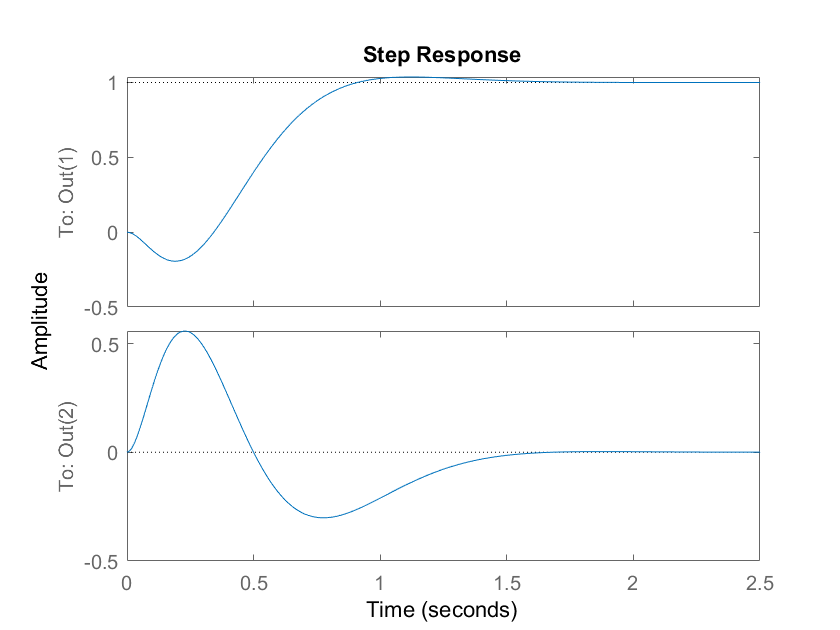

figure
step(sys)